clc
clear
w=windmatlab

profile on
M=1000000       %轨道数

M = 1000000

s0=1000         %期初价格

s0 = 1000

r=0.14          %给定收益率

r = 0.1400

mu=0.048        %无风险利率

mu = 0.0480

sigma=0.2       %波动率

sigma = 0.2000

d=0.006         %股息率

d = 0.0060

b_in=0.75       %敲入边界

b_in = 0.7500

b_out=1.05      %敲出边界

b_out = 1.0500

### 请输入1年期雪球收益凭证的初始日期（格式如**'20210401'**）:

StartDate=input('初始日期：','s')

StartDate = '20210427'


tic

[knockin_days,knockout_days,N1,N2]=DateProcessor(StartDate);

toc

历时 0.567275 秒。



R=randn(M,N1);

tic

V=MCSE(knockin_days,knockout_days,N1,N2,R,M,s0,r,mu,sigma,d,b_in,b_out);

toc

历时 5.420784 秒。




V

V = 1.0022


if V > 1
    p=roundn((V-1)*100,-3);
    disp(['该收益凭证价格若不超过本金的',num2str(p),'%则值得购买，反之不值得购买'])
else
    disp('该收益凭证不值得购买')
end

该收益凭证价格若不超过本金的0.218%则值得购买，反之不值得购买


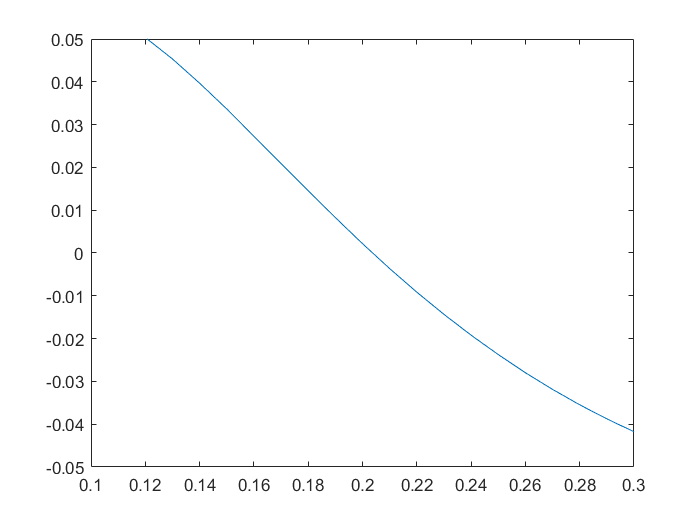

tic

i=1;
for sigma = 0.1:0.01:0.3
    y(i)=MCSE(knockin_days,knockout_days,N1,N2,R,M,s0,r,mu,sigma,d,b_in,b_out)-1;
    i=i+1;
end

x=0.1:0.01:0.3;

plot(x,y)
axis([0.1 0.3 -0.05 0.05])


toc

历时 127.034730 秒。


tic

u=0.16;
v=0.24;

while abs(MCSE(knockin_days,knockout_days,N1,N2,R,M,s0,r,mu,(u+v)/2,d,b_in,b_out)-1) > 0.0001
    if MCSE(knockin_days,knockout_days,N1,N2,R,M,s0,r,mu,(u+v)/2,d,b_in,b_out)-1>0
        u=(u+v)/2;
    else
        v=(u+v)/2;
    end
end

threshold=(u+v)/2

threshold = 0.2038


toc

历时 62.963691 秒。
